# CARRGO Model

This is a demonstration based on the CARRGO model [1]. It models the interaction of cancer cells and CAR T-cells which are used to destroy them and is a variation of Lotka-Volterra predator-prey equations. The system of ODEs is 


$$\begin{array}{l}
\frac{\textrm{dx}}{\textrm{dt}}=\rho x\left(1-\frac{x}{\gamma }\right)-\kappa_1 \textrm{xy}\\
\frac{\textrm{dy}}{\textrm{dt}}=\kappa_2 \textrm{xy}-\theta y
\end{array}$$


$x$ is the density of cancer cells and$y$ is the density of CAR T-cells. The parameters are

- $\kappa_1$: The killing rate of the CAR T-cells.

- $\kappa_2$: Net rate of proliferation of CAR T-cells

- $\theta$: Death rate of CAR T-cells

- $\rho$: Net growth rate of cancer cells

- $\gamma$: Cancer cell carrying capacity

For a discussion of sensitivity analysis in MATLAB using this model as an example, refer to [Faster Ordinary Differential Equations (ODEs) solvers and Sensitivity Analysis of Parameters: Introducing SUNDIALS support in MATLAB » The MATLAB Blog - MATLAB & Simulink (mathworks.com)](https://blogs.mathworks.com/matlab/2024/04/17/faster-ordinary-differential-equations-odes-solvers-and-sensitivity-analysis-of-parameters-introducing-sundials-support-in-matlab/)

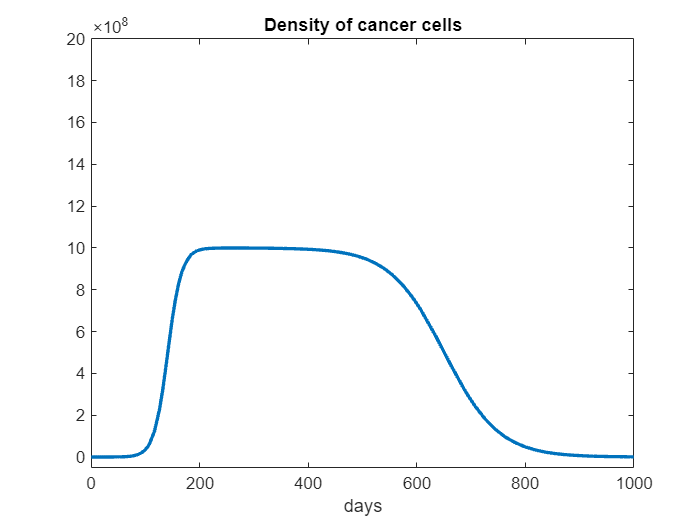

% Set parameters
kappa1 =6*10^-9;
kappa2 =2*10^-11;
theta =1 * 10^-6;
rho = 8 * 10^-2;
gamma = 1 * 10^9;

% Set up ODE system
F = ode();
F.ODEFcn = @(t,x,p) [ p(4) * x(1) * (1-x(1) / p(5))-p(1) * x(1) * x(2); p(2)* x(1) * x(2)-p(3) * x(2)];
F.InitialValue = [1.25*10^4 , 6.25*10^2];
F.Parameters = [kappa1,kappa2,theta, rho, gamma];
F.Solver = "cvodesnonstiff";

% Compute solution
sol = solve(F,0,1000);

% Plot solution
figure
plot(sol.Time,sol.Solution(1,:),LineWidth=2)
title("Density of cancer cells")
xlabel("days")
ylim([-0.5*10^8 20*10^8])

**References**

[1] Sahoo P, Yang X, Abler D, Maestrini D, Adhikarla V, Frankhouser D, Cho H, Machuca V, Wang D, Barish M, Gutova M, Branciamore S, Brown CE, Rockne RC. [Mathematical deconvolution of CAR T-cell proliferation and exhaustion from real-time killing assay data](https://www.ncbi.nlm.nih.gov/pmc/articles/PMC7014796/). J R Soc Interface. 2020 Jan;17(162):20190734. [doi: 10.1098/rsif.2019.0734](https://www.ncbi.nlm.nih.gov/pmc/articles/PMC7014796/). Epub 2020 Jan 15. PMID: 31937234; PMCID: PMC7014796.